# Stima Giunto 1 su SCARA. 

Modello giunto 1

Si ipotizza che il robot sia disaccoppiato (è un'approssimazione), si aggiunge un segnale eccitante al giunto 1 mentre si cerca di mantenere fermo il giunto 2 (poi si inverte).

sarebbe ideale avere il controllore del giunto 1 abbastanza blando per non compensare il segnale eccitante, mentre quello del giunto 2 dovrebbe essere più aggressivo. Non è sempre facile farlo.

E' possibile usare un approccio iterativo:

- identifico il modello del giunto 1 con un controllore blando su 1 e 2.

- taro il controllore 1 per essere reattivo, lascio blando il controllore 2

- identifico il modello del giunto 2

- taro il controllore 2 per essere reattivo, riporto il controllore 1 a valori blandi

- identifico il modello del giunto 1 e verifico se è cambiato di molto se si, ripeto la taratura del 2 e cosi via.

clc;clear all;close all;
set(0, 'defaultFigurePosition',  [ 1, 1, 800, 600]); % figure più grandi

robot=ElasticRoboticSystem('progetto1');
robot.show;

This system has 4 outputs:
- position_1
- position_2
- velocity_1
- velocity_2
This system has 2 inputs:
- torque_1, with maximum limit = 840.000000
- torque_2, with maximum limit = 220.000000


Tc = robot.getSamplingPeriod;
robot.initialize;

load +scara_data/scara_controller_object.mat
decentralized_ctrl.initialize;
decentralized_ctrl.setUMax(robot.getUMax);


## Identificazione

Definisco segnale di identificazione

igiunto=1;

#### Portante

omega_portante=1;
ampiezza_portante=500;
T_portante=2*pi/omega_portante;
t=(0:Tc:(3.1*T_portante))';
portante=ampiezza_portante*sin(omega_portante*t);

#### Segnale eccitante

w0=omega_portante*30; %rad/s
w1=pi/Tc; %rad/s
control_action_identificazione = chirp(t,w0/2/pi,t(end),w1/2/pi, 'logarithmic');

ampliezza_identificazione=150;

sommo

exciting_signal=zeros(length(t),robot.getInputNumber);
exciting_signal(:,igiunto)=portante+ control_action_identificazione*ampliezza_identificazione;


Simulo il sistema

aspetto qualche secondo perchè il robot si stabilizzi

measured_output = robot.readSensorValue();
q0=measured_output(1:2);
Dq0=measured_output(3:4);
DDq0=[0;0];

% initial reference is equal to the inital state of the robot
reference=[q0;Dq0;DDq0];
uff=[0;0];
for idx=1:5e3
    measured_output = robot.readSensorValue();
    joint_torque = decentralized_ctrl.computeControlAction(reference,measured_output,uff);
    % apply torque
    robot.writeActuatorValue(joint_torque);
    % simulate
    robot.simulate();
end

inizio la prova


for idx=1:length(t)
    measured_output = robot.readSensorValue();
    uff=exciting_signal(idx,:)';
    joint_torque = decentralized_ctrl.computeControlAction(reference,measured_output,uff);
    % apply torque
    robot.writeActuatorValue(joint_torque);
    % simulate
    robot.simulate();
    control_action(idx,:)=joint_torque;
    measured_signal(idx,:)=measured_output;
    
    
end
joint_position=measured_signal(:,1:2);
joint_velocity=measured_signal(:,3:4);





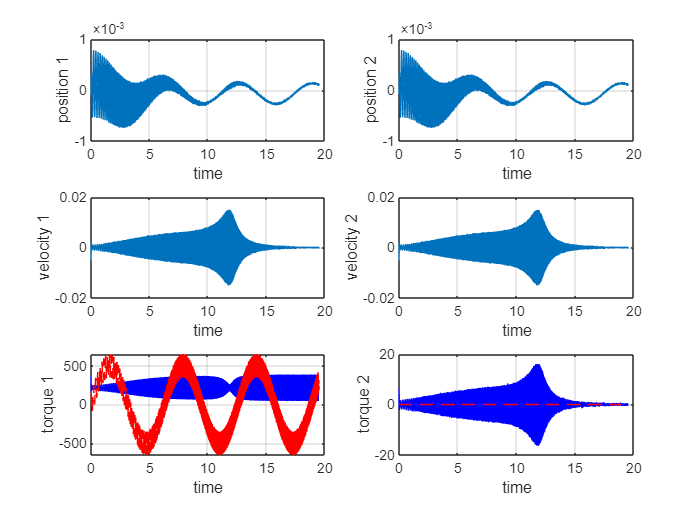

figure(1)
subplot(3,2,1)
plot(t,joint_position(:,1))
xlabel('time')
ylabel('position 1')
grid on

subplot(3,2,3)
plot(t,joint_velocity(:,2))
xlabel('time')
ylabel('velocity 1')
grid on

subplot(3,2,5)
plot(t,control_action(:,1),'-b',t,exciting_signal(:,1),'--r')
xlabel('time')
ylabel('torque 1')
grid on

subplot(3,2,2)
plot(t,joint_position(:,1))
xlabel('time')
ylabel('position 2')
grid on

subplot(3,2,4)
plot(t,joint_velocity(:,2))
xlabel('time')
ylabel('velocity 2')
grid on

subplot(3,2,6)
plot(t,control_action(:,2),'-b',t,exciting_signal(:,2),'--r')
xlabel('time')
ylabel('torque 2')
grid on

Salvo i risultati

figure

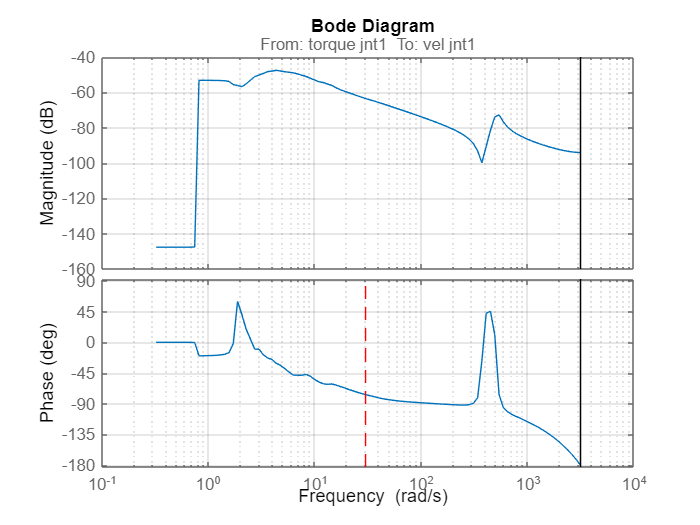

experiment=iddata(joint_velocity(:,igiunto),control_action(:,igiunto),Tc);
experiment.InputName='torque jnt1';
experiment.OutputName='vel jnt1';
experiment_freqresp = spafdr(experiment);

bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h=bodeplot(experiment_freqresp, bode_opts);
grid on
hold on
hold on
plot(w0*[1 1],ylim,'--r')
hold off
grid on